# Lab 4: Working with 'real' data

Jeff Jiang

Lab Partners: Avis Soval, Thomas Conaway

clc; clear; close all;
h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:);

## Problem 1

In problem we were given with huge amount of data points. The data point represent the time (in gps seconds), the Solar phase (deg) showing the position of the sun relative to the orbit, the Earth longitude (deg) giving the position of the spacecraft relative to the ground, and the particle counts for every 100 milliseconds. The data points are collected by a gamma-ray satellite orbiting in low Earth orbit. While satellite is looking for gamma-ray bursts, but most of the particles detected are background cosmic rays.

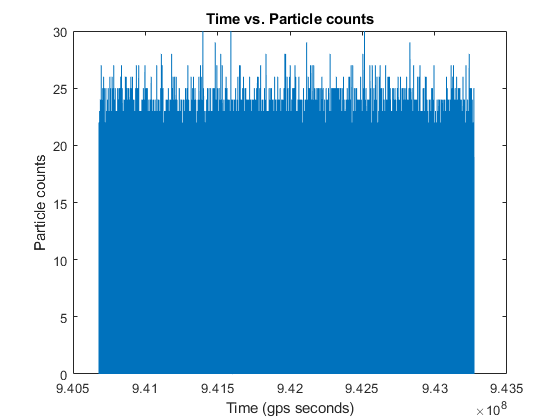

time = mydata(:,1);
solar_phase = mydata(:,2);
earth_longitude = mydata(:,3);
particle_counts = mydata(:,4);
figure;
plot(time,particle_counts);
title('Time vs. Particle counts');
xlabel('Time (gps seconds)');
ylabel('Particle counts');

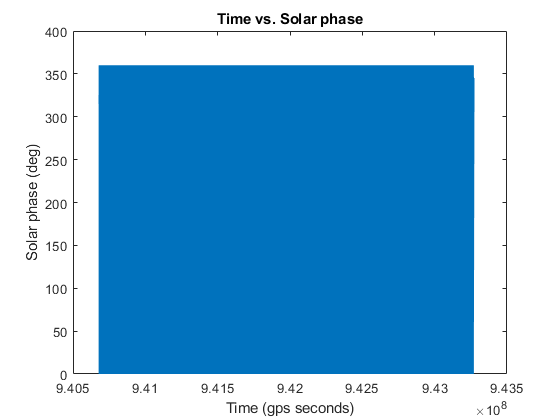

figure;
plot(time,solar_phase);
title('Time vs. Solar phase');
xlabel('Time (gps seconds)');
ylabel('Solar phase (deg)');

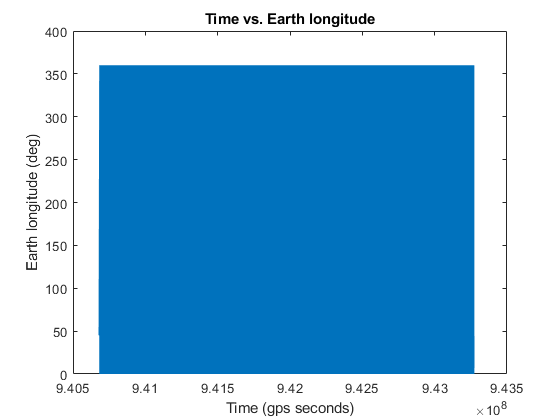

figure;
plot(time,earth_longitude);
title('Time vs. Earth longitude');
xlabel('Time (gps seconds)');
ylabel('Earth longitude (deg)');

The figures above is unreadable because the datasets hold very large data points. We know the number of particles detected are every 100 milliseconds, and satellite is in an approximately 90-minute orbit. For one orbit will take approximately 5400000 milliseconds. Since the number of particles are only detected very 100 milliseconds, the total number of times of the particle was detected is approximately 54000 times for one orbit. We will work with the time for 6 orbits to graph the datasets to check any patent. 

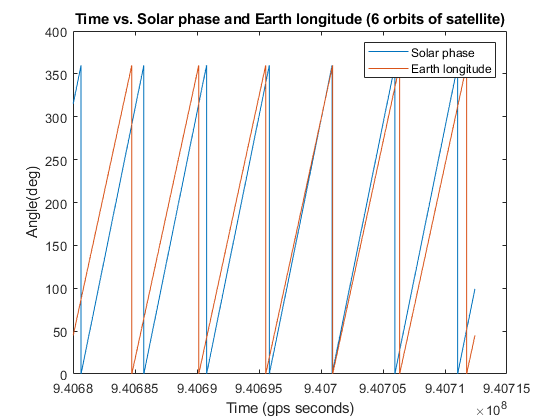

period = 54000;
orbits = 6;
figure;
plot(time(1:period*orbits),solar_phase(1:period*orbits));
hold on;
plot(time(1:period*orbits),earth_longitude(1:period*orbits));
title('Time vs. Solar phase and Earth longitude (6 orbits of satellite)');
xlabel('Time (gps seconds)');
ylabel('Angle(deg)');
legend('Solar phase', 'Earth longitude');

As show on Time vs. Solar phase and Earth longitude figure the data are not random. There is consistent sawtooth wave pattern to Solar phase and Earth longitude related to time. The pattern make sense for the Solar phase because position of the sun relative to the orbit will vary between 0 to 360 degree. At a point when the position of the sun relative to the orbit reach to 360 degree. As the orbit moves the angle become 0 degree. That explain the sawtooth wave pattern. The pattern make sense for the Earth longitude because position of the spacecraft relative to the ground will vary between 0 to 360 degree as will. As show on the graph the period between the Solar phase and Earth longitude is different. 

solar_period_time = time(islocalmin(solar_phase));
earth_period_time = time(islocalmin(earth_longitude));
solar_period_time_even = solar_period_time(2:2:end);
solar_period_time_odd = solar_period_time(1:2:end - 1);
solar_period = mean(solar_period_time_even - solar_period_time_odd);
solar_period = solar_period / 60;
earth_period_time_even = earth_period_time(2:2:end);
earth_period_time_odd = earth_period_time(1:2:end - 1);
earth_period = mean(earth_period_time_even - earth_period_time_odd);
earth_period = earth_period / 60;
disp("The Solar period is " + solar_period + " minute." + " The Earth period is " + earth_period + " minute." )

The Solar period is 84.3611 minute. The Earth period is 90 minute.


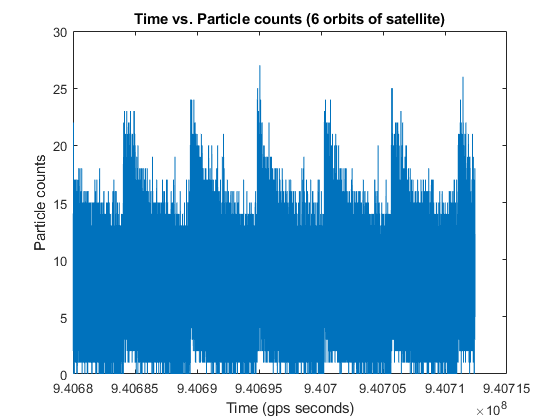

figure;
plot(time(1:period*orbits),particle_counts(1:period*orbits));
title('Time vs. Particle counts (6 orbits of satellite)');
xlabel('Time (gps seconds)');
ylabel('Particle counts');

As show on Time vs. Particle counts figure the data are not random. There is jumps in the measurement correlate to the number of the orbits. Since the jumps appear to be periodic and the number of periods is the same as the number of the orbits. The jump means there is additional source of radiation at some point in the orbit. I find South Atlantic Anomaly can be the reason why the jump appears. Since the Earth's magnetic field is weakest at the SAA. The satellite will receive more particle counts. 

As show on Time vs. Particle counts figure the data are discrete measurement. The distribution will be more likely to be discrete as well. The jumps look like discrete independent events. That is why I think Poisson distribution will fit the distribution curve and the lambda for the distribution would be the mean of the particle counts. 

(The **South Atlantic Anomaly** (SAA) is an area where the Earth's inner [Van Allen radiation belt](https://en.wikipedia.org/wiki/Van_Allen_radiation_belt) comes closest to the [Earth](https://en.wikipedia.org/wiki/Earth)'s surface, dipping down to an altitude of 200 kilometres (120 mi). This leads to an increased [flux](https://en.wikipedia.org/wiki/Flux) of energetic particles in this region and exposes orbiting [satellites](https://en.wikipedia.org/wiki/Satellite) to higher-than-usual levels of radiation.

The effect is caused by the [non-concentricity](https://en.wikipedia.org/wiki/Concentric) of the Earth and its magnetic [dipole](https://en.wikipedia.org/wiki/Dipole). The SAA is the near-Earth region where the [Earth's magnetic field](https://en.wikipedia.org/wiki/Earth%27s_magnetic_field) is weakest relative to an idealized Earth-centered dipole field.)

mean_particle_counts = mean(particle_counts);
disp("The mean for the particle counts is " + mean_particle_counts);

The mean for the particle counts is 7.0973


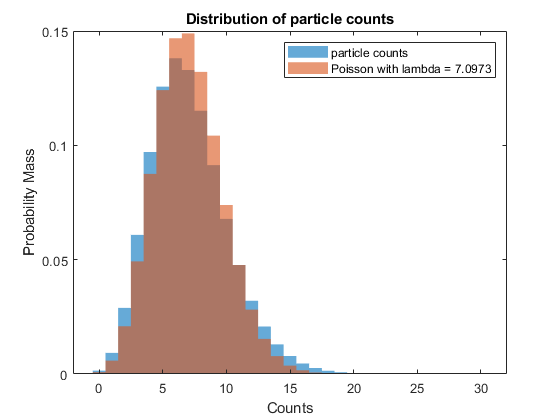

figure;
histogram(particle_counts,"Normalization","pdf","EdgeColor","none");
hold on
poisson = makedist("Poisson", "lambda", mean_particle_counts);
poisson_vals = random(poisson, [1 length(particle_counts)]);
histogram(poisson_vals,"Normalization","pdf","EdgeColor","none");
title('Distribution of particle counts');
xlabel('Counts');
ylabel('Probability Mass');
legend('particle counts', ['Poisson with lambda = ' num2str(mean_particle_counts)]);

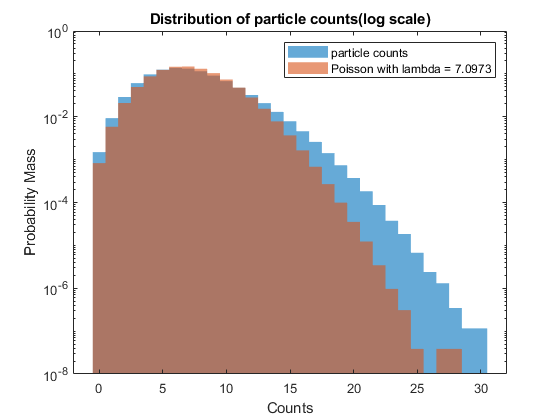

figure;
histogram(particle_counts,"Normalization","pdf","EdgeColor","none");
hold on;
histogram(poisson_vals,"Normalization","pdf","EdgeColor","none");
title('Distribution of particle counts(log scale)');
xlabel('Counts');
ylabel('Probability Mass');
legend('particle counts', ['Poisson with lambda = ' num2str(mean_particle_counts)]);
set(gca, 'YScale', 'log');

As showed, the data do not follow the Poisson distribution on the log scaled graph. There are many outliers. The data we used have much more measurements of high particle counts. In order to make the graph fit better we can split the data into two part. The part that is under SAA and the normal part. Assuming that SAA region is between 40 degrees and 310 degrees earth longitude.

normal_index = (earth_longitude > 40) & (earth_longitude < 310);
SAA_index = ~normal_index;
normal_particle_counts = particle_counts(normal_index);
SAA_particle_counts = particle_counts(SAA_index);
normal_time = time(normal_index);
SAA_time = time(SAA_index);
mean_normal = mean(normal_particle_counts);
mean_SAA = mean(SAA_particle_counts);
orbits2 = 2;

orbits2 = 2

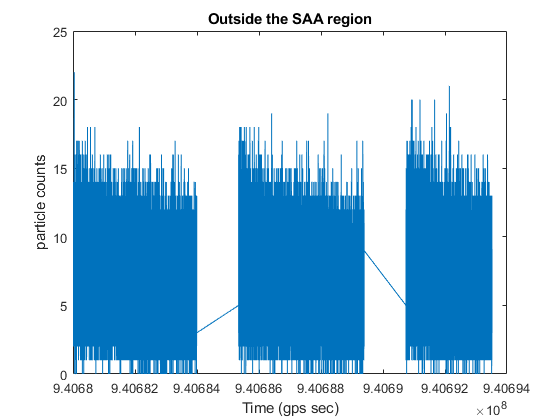

figure;
plot(normal_time(1:period*orbits2),normal_particle_counts(1:period*orbits2));
title('Outside the SAA region');
xlabel('Time (gps sec)');
ylabel('particle counts');

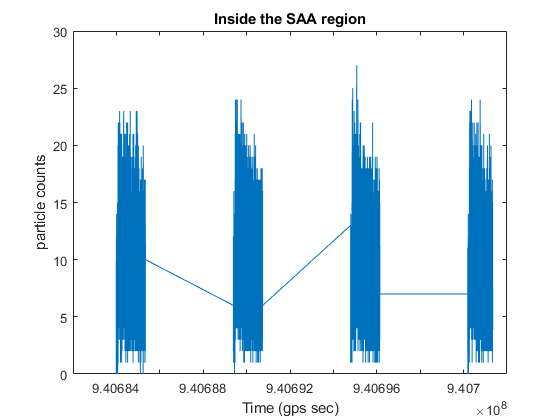


figure;
plot(SAA_time(1:period*orbits2),SAA_particle_counts(1:period*orbits2));
title('Inside the SAA region');
xlabel('Time (gps sec)');
ylabel('particle counts');

As you can see, I separated the overall data. The data became two part, the part under the SAA region and the part is not under SAA region. The part inside the SAA region over all has the higher particle counts. The part outside the SAA region over all has the lesser particle counts. The variation of the particle count is less than overall data. Next, I am plot both region in the Poisson distribution. 

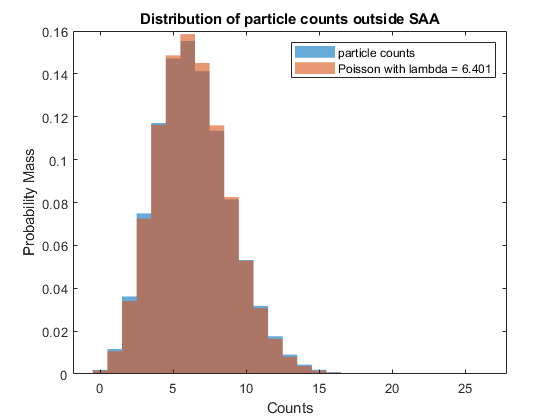


figure;
histogram(normal_particle_counts,"Normalization","pdf","EdgeColor","none");
hold on;
poisson = makedist("Poisson", "lambda", mean_normal);
poisson_vals = random(poisson, [1 length(normal_particle_counts)]);
histogram(poisson_vals,"Normalization","pdf","EdgeColor","none")
title('Distribution of particle counts outside SAA');
xlabel('Counts');
ylabel('Probability Mass');
legend('particle counts', ['Poisson with lambda = ' num2str(mean_normal)]);

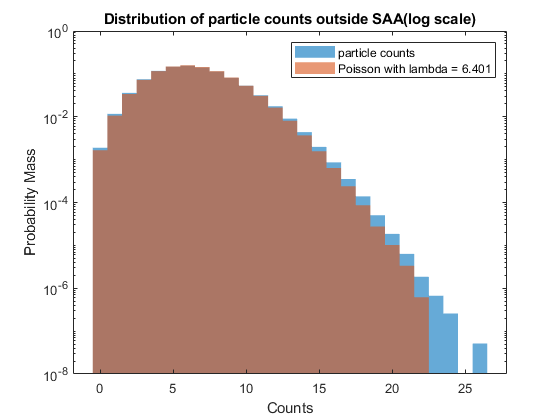

figure;
histogram(normal_particle_counts,"Normalization","pdf","EdgeColor","none");
hold on;
histogram(poisson_vals,"Normalization","pdf","EdgeColor","none")
title('Distribution of particle counts outside SAA(log scale)');
xlabel('Counts');
ylabel('Probability Mass');
legend('particle counts', ['Poisson with lambda = ' num2str(mean_normal)]);
set(gca, 'YScale', 'log');

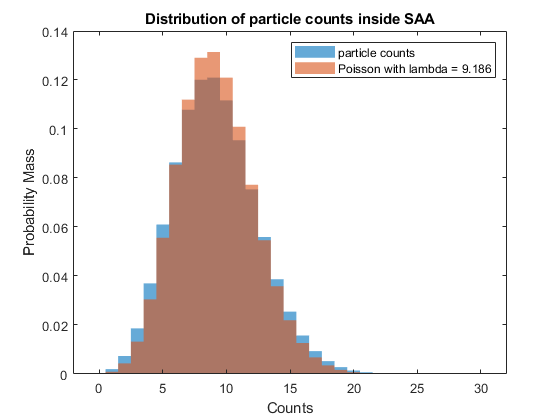

figure;
histogram(SAA_particle_counts,"Normalization","pdf","EdgeColor","none");
hold on;
poisson = makedist("Poisson", "lambda", mean_SAA);
poisson_vals = random(poisson, [1 length(SAA_particle_counts)]);
histogram(poisson_vals,"Normalization","pdf","EdgeColor","none")
title('Distribution of particle counts inside SAA');
xlabel('Counts');
ylabel('Probability Mass');
legend('particle counts', ['Poisson with lambda = ' num2str(mean_SAA)]);

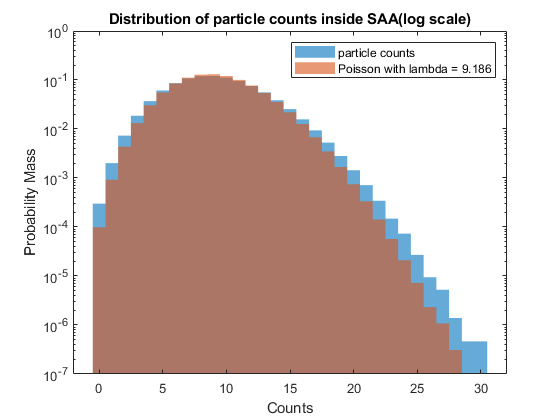

figure;
histogram(SAA_particle_counts,"Normalization","pdf","EdgeColor","none");
hold on;
histogram(poisson_vals,"Normalization","pdf","EdgeColor","none")
title('Distribution of particle counts inside SAA(log scale)');
xlabel('Counts');
ylabel('Probability Mass');
legend('particle counts', ['Poisson with lambda = ' num2str(mean_SAA)]);
set(gca, 'YScale', 'log');

I think this way the data is better represented. I think with more precise range of earth longitude for SAA region. The data will fit more accurately. 

Next, we what to know what is the minimum quantity of particle count in 100 milliseconds can be count as  $5\sigma$discovery, inside the SAA region and outside the SAA region?

sigma5 = normcdf(-5, 0, 1);
threshold_normal = abs(icdf('Poisson', 1-sigma5, mean_normal))

threshold_normal = 23

threshold_SAA = abs(icdf('Poisson', 1-sigma5, mean_SAA))

threshold_SAA = 28

Outside the SAA region we need to see 23 particle counts or more per 100 milliseconds to claim a  $5\sigma$ discovery. Inside the SAA region we need to see 28 particle counts or more per 100 milliseconds to claim a  $5\sigma$ discovery. 

## Problem 2

In problem 2 we were given with 10 telescope images(simulated). I will be looking for the faintest stars among the background. 

clear;
h5disp("images.h5");

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


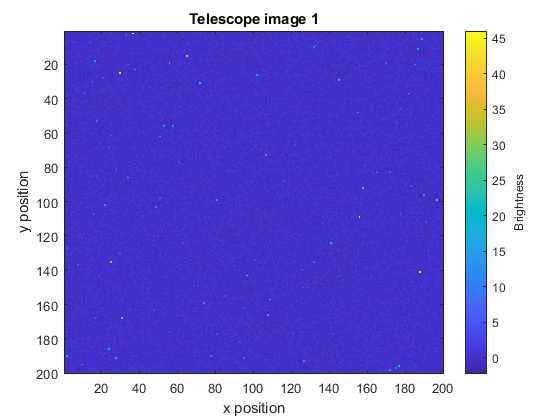

mydata = h5read("images.h5",'/imagestack');

figure;
image_one = squeeze(mydata(1,:,:));
imagesc(image_one)
h = colorbar;
ylabel(h,'Brightness');
title('Telescope image 1');
xlabel('x position');
ylabel('y position');

Above show the first Telescope image. That image shows the brightness at night sky. As the sidebar show brightness goes form blue to yellow. Yellow as the brightest. 

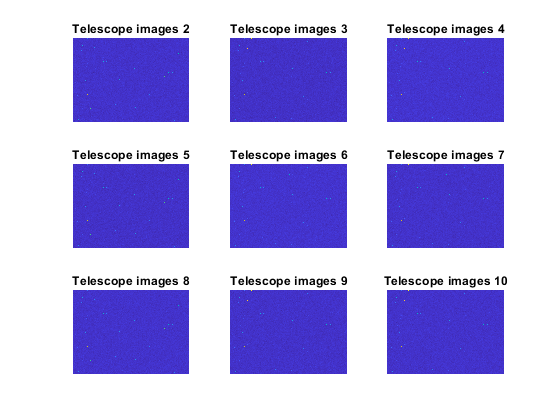

figure;
for i = 2:10
    one_of_image = squeeze(mydata(i,:,:));
    subplot(3,3,i-1);
    imagesc(one_of_image)
    axis off;
    title("Telescope images " + i);
end

Above show the rest Telescope images.

Since most part of the image is not bright. most signal we get are blue. In order to find the faintest stars among the background, I will plot the average signal distribution of all the images. Then find a Gaussian distribution fit the plot. So, most signal that is not under the Gaussian distribution will be the outliers. 

figure;
mean_dist = mean(mydata, 1);
relevant_mean = mean_dist(mean_dist < 1);
mean_real  = mean(relevant_mean);
std_real = std(relevant_mean);
disp("Gaussian with Mean " + mean_real + ", Std dev " + std_real);

Gaussian with Mean -0.00012927, Std dev 0.17784


disp("5 sigma is " + 5 * std_real);

5 sigma is 0.88919


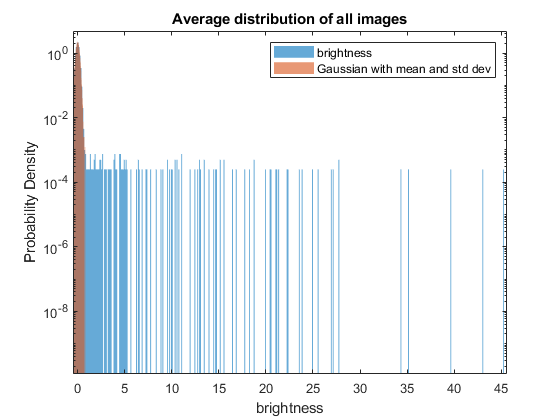

Gaussian = makedist("Normal","mu",mean_real,"sigma",std_real);
Gaussian_vals = random(Gaussian, [1 length(relevant_mean)]);

histogram(mean_dist, 'EdgeColor', 'none',"Normalization","pdf");
hold on;
histogram(Gaussian_vals,'EdgeColor', 'none',"Normalization","pdf");
set(gca, 'YScale', 'log');
title('Average distribution of all images')
xlabel('brightness')
ylabel('Probability Density')
legend( 'brightness', "Gaussian with mean and std dev ");

Above is the graph for signal's average distribution of all images. There is signal contamination, since the average distribution of all image shows the measurement of brightness match with the Gaussian distribution most of the time, but there are outliers (above  $5\sigma$ measurement of brightness) with some probability density. This distribution is not time dependent since I use the average brightness of the all images.

Since we are looking for the faintest stars among the background. We what to set an upper limit for the brightness. We are only looking for the stars that is just slightly above$\;5\sigma$ .

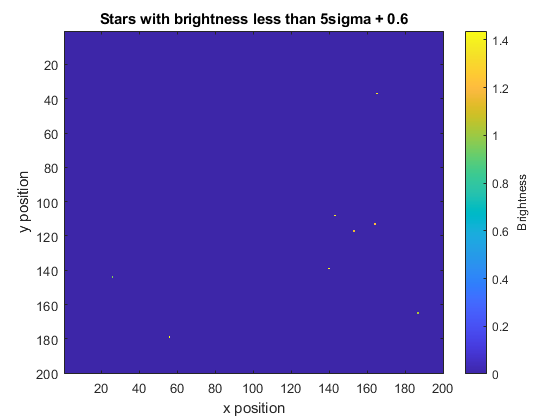

all_objects = mean_dist .* (mean_dist > 5*std_real & mean_dist < 5*std_real +0.6);
figure;
imagesc(squeeze(all_objects));
h2 = colorbar;
title('Stars with brightness less than 5sigma + 0.6')
ylabel(h2,'Brightness');
xlabel('x position');
ylabel('y position');

Above are the position and brightness’s of the 8 faintest stars seen in average of all Telescope images, the faintest being located at x position of 25 and y position of 145.

Since my partner searched for bright transient events. My partner will work with the differences between Telescope images. My partner's pdf will be different. 